# C.2b - Projecte Final de Visió per Ordenador

`Joan Bernaus Casadesús i Joan Bennàssar Martín`

`VO - GIA - FIB - UPC`

`Barcelona, a gener de 2025`

## **Enunciat**

La segona part del segon exercici consisteix a implementar una versió pròpia d’un algoritme clàssic de reconeixement de caràcters. Aquest algoritme té dues fases:

- Segmentar la imatge (o una regió d’interès) de manera que cada caràcter formi una component connexa independent.

- Aplicar un procés d’esqueletització que permeti comparar cada caràcter alfanumèric amb un model donat.

Aplica aquest algoritme a una imatge amb text (aquesta imatge pot ser diferent de les imatges de la base de dades *book covers*) i compara els resultats amb els obtinguts utilitzant la funció de MATLAB `ocr`, que realitza una tasca similar.

## `1. Carregar la imatge`

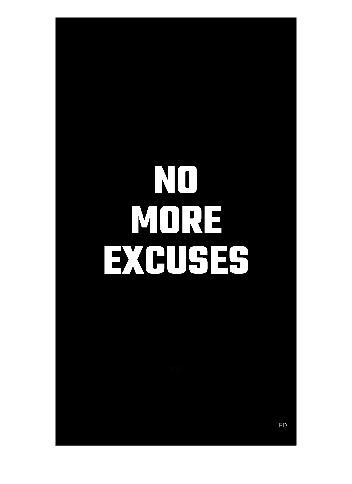

image_path = "C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\IMAGE2.png";
img = imread(image_path);
imshow(img);

## 2. Processar i Segmentar la imatge

El codi segmenta una imatge per identificar caràcters individuals com a components independents. Primer, la imatge es converteix a escala de grisos i es binaritza utilitzant el mètode d'Otsu per separar els objectes del fons. A continuació, es netegen components petits no desitjats i es reetiqueten les regions connexes, assignant una etiqueta única a cada regió independent. Es filtren les components segons la seva àrea, eliminant aquelles que no compleixen un llindar mínim per assegurar que només es conserven elements rellevants. També es calculen les bounding boxes per a cada component, que delimiten els caràcters amb rectangles per facilitar-ne la identificació.

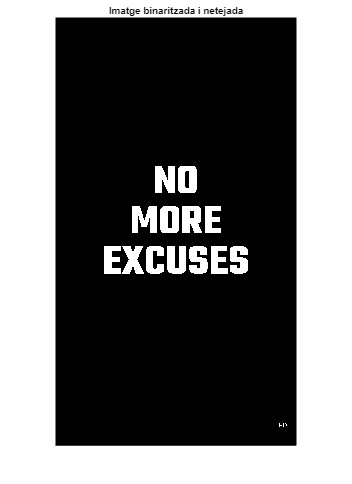

% Convertir la imatge a escala de grisos
img_gray = rgb2gray(img);

% Binaritzar la imatge utilitzant un llindar automàtic (Otsu)
threshold = graythresh(img_gray); % Llindar calculat automàticament
binary_img = imbinarize(img_gray, threshold);

% Invertir la imatge 
binary_img = ~binary_img;

% Eliminar components petits
binary_img_cleaned = bwareaopen(binary_img, 100); 
binary_img_cleaned = ~binary_img_cleaned;

% Visualitzar la imatge binaritzada i netejada
figure;
imshow(binary_img_cleaned);
title('Imatge binaritzada i netejada');

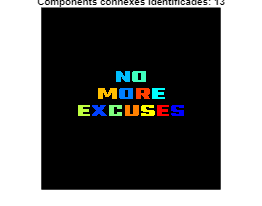

% Etiquetar les components connexes
[labels, num] = bwlabel(binary_img_cleaned);

% Obtenir propietats de cada component
stats = regionprops(labels, 'BoundingBox', 'Centroid', 'Area');

% Eliminar components més petites que una certa àrea mínima
min_area = 200; % Ajusta aquest valor segons les necessitats
for i = 1:num
    if stats(i).Area < min_area
        labels(labels == i) = 0; % Eliminar la component petita
    end
end

% Reetiquetar les components després d'eliminar-ne
[labels, num] = bwlabel(labels);

% Obtenir de nou les propietats per a les noves components
stats = regionprops(labels, 'BoundingBox', 'Centroid');

centroids = reshape([stats.Centroid], 2, []).'; % Coordenades dels centroides
[~, idx] = sortrows(centroids, [2, 1]); 
stats = stats(idx); 

% Visualitzar les components connexes amb etiquetes
figure;
imshow(label2rgb(labels, 'jet', 'k', 'shuffle'));
title(['Components connexes identificades: ', num2str(num)]);

## 3. Esqueletització i Reconeixement de Caràcters

Aquest codi implementa la segona fase de l’algoritme de reconeixement de caràcters, centrant-se en l’esqueletització i la comparació amb un dataset de referència. Primer, s’organitzen i es processen les imatges del dataset, agrupades en carpetes per cada lletra(10 imatges per carpeta de cada lletra). Per a cada imatge del dataset, es binaritza i es selecciona la component més gran, de la qual s'obté l’esquelet. Després, es calculen descriptors numèrics que capturen les característiques clau de l’esquelet i es guarda la mitjana d’aquests descriptors per a cada lletra(cada subcarpeta del dataset).

A continuació, es processen les components detectades en la imatge original. Cada component es retalla segons la seva bounding box i es calcula el seu esquelet. A partir d’aquí, es generen descriptors i es comparen amb les mitjanes de cada lletra mitjançant una distància chi-2, assegurant que els descriptors tenen dimensions consistents. La lletra del dataset amb la distància mínima es considera la millor coincidència per a la component analitzada. Finalment, es guarda la lletra identificada per a cada component, .

% Llista per guardar la lletra més semblant per a cada component
detected_letters = cell(1, num);

dataset_path = "C:\Users\joanb\Desktop\IA\Tercer\VO\PF_VO\EX2\Text_Data";
letters_folders = dir(dataset_path);
letters_folders = letters_folders([letters_folders.isdir] & ~ismember({letters_folders.name}, {'.', '..'}));

% Calcular les mitjanes dels descriptors per cada lletra del dataset
letter_descriptors = struct();

for i = 1:numel(letters_folders)
    letter_name = letters_folders(i).name;
    letter_path = fullfile(letters_folders(i).folder, letter_name);

    % Llegeix totes les imatges de la subcarpeta
    letter_images = dir(fullfile(letter_path, '*.png'));

    if isempty(letter_images)
        warning('La carpeta "%s" no conté imatges.', letter_path);
        continue;
    end

    % Vector per emmagatzemar descriptors de totes les imatges d'aquesta lletra
    all_descriptors = [];

    for j = 1:numel(letter_images)
        % Llegir i processar la imatge del dataset
        image_path = fullfile(letter_images(j).folder, letter_images(j).name);
        image = imread(image_path);

        % Comprovar si la imatge és RGB i convertir a escala de grisos si cal
        if size(image, 3) == 3
            img_gray = rgb2gray(image);
        else
            img_gray = image;
        end

        % Binaritzar la imatge
        threshold = graythresh(img_gray);
        binary_img = imbinarize(img_gray, threshold);
        binary_img = ~binary_img;

        % Seleccionar la component més gran
        [labels_dataset, num_dataset] = bwlabel(binary_img);
        stats_dataset = regionprops(labels_dataset, 'BoundingBox', 'Area');

        max_area = 0;
        selected_component = [];
        for d = 1:num_dataset
            if stats_dataset(d).Area > max_area
                max_area = stats_dataset(d).Area;
                selected_component = imcrop(binary_img, stats_dataset(d).BoundingBox);
            end
        end

        if isempty(selected_component)
            warning('No s''ha trobat cap component vàlida a la imatge "%s".', image_path);
            continue;
        end

        % Processar la component i obtenir l'esquelet
        skeleton_dataset = process_segmented_component(selected_component);

        % Calcular descriptors de la imatge del dataset
        dataset_descriptors = calculate_skeleton_descriptors(skeleton_dataset);

        % Assegurar que els descriptors tinguin la mateixa mida
        if isempty(all_descriptors)
            % Si és el primer descriptor, l'assignem directament
            all_descriptors = dataset_descriptors;
        else
            % Assegurar que els descriptors tinguin la mateixa mida
            max_length = max(length(all_descriptors), length(dataset_descriptors));
            dataset_descriptors = pad_or_truncate(dataset_descriptors, max_length);
            all_descriptors = [all_descriptors; dataset_descriptors]; % Concatenar de manera segura
        end
    end

    % Calcular la mitjana dels descriptors per a aquesta lletra
    if ~isempty(all_descriptors)
        letter_descriptors.(letter_name) = mean(all_descriptors, 1);
    else
        warning('No s''han pogut calcular descriptors per a la lletra "%s".', letter_name);
    end
end

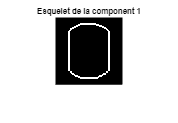

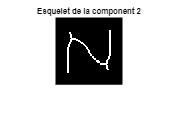

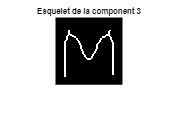

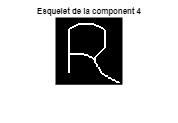

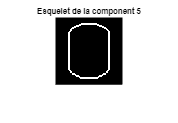

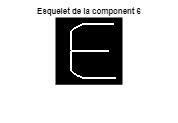

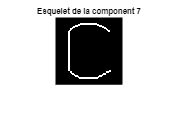

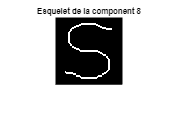

% Processar cada component detectada
for k = 1:num
    % Retallar la component segons la BoundingBox
    cropped_component = imcrop(binary_img_cleaned, stats(k).BoundingBox);

    % Processar la component i obtenir l'esquelet
    skeleton = process_segmented_component(cropped_component);

    % Plotejar l'esquelet
    figure;
    imshow(skeleton);
    title(sprintf('Esquelet de la component %d', k));

    % Calcular descriptors de la component esqueletitzada
    component_descriptors = calculate_skeleton_descriptors(skeleton);

    % Inicialitzar la millor coincidència
    best_match = '';
    min_distance = Inf;

    % Comparar amb les mitjanes de les lletres
    letter_names = fieldnames(letter_descriptors);
    for i = 1:numel(letter_names)
        current_letter = letter_names{i};
        mean_descriptors = letter_descriptors.(current_letter);

        % Assegurar dimensions consistents
        max_length = max(length(component_descriptors), length(mean_descriptors));
        component_descriptors = pad_or_truncate(component_descriptors, max_length);
        mean_descriptors = pad_or_truncate(mean_descriptors, max_length);

        % Calcular distància chi-2 entre descriptors
        distance = sum(((component_descriptors - mean_descriptors).^2) ./ ...
           (component_descriptors + mean_descriptors + eps));

        % Actualitzar la millor coincidència si cal
        if distance < min_distance
            min_distance = distance;
            best_match = current_letter;
        end
    end

    % Guardar la millor coincidència
    detected_letters{k} = best_match;
end

## Funcions Auxiliars

Aquestes funcions auxiliars complementen el procés principal d'esqueletització i càlcul de descriptors, garantint que les característiques dels components es generin, normalitzin i alineïn correctament per a la seva comparació.

`calculate_skeleton_descriptors`

Aquesta funció genera descriptors per a un component esqueletitzat. Combina diferents tipus de característiques:

- **Descriptors HOG**: Es calculen característiques basades en gradients per capturar informació d'estructura local amb `extractHOGFeatures`.

- **Característiques geomètriques bàsiques**: Inclouen el perímetre, l'àrea, la compacitat (relació entre perímetre i àrea) i la relació d'aspecte (amplada/alçada) del component.

- **Descriptors del contorn**: Si el component té un contorn vàlid, es calcula la transformada de Fourier del contorn per obtenir-ne els primers 10 coeficients, capturant patrons de forma global.

Finalment, els descriptors es compacten en un únic vector i es normalitzen perquè totes les dimensions tinguin el mateix pes durant la comparació.

`process_segmented_component`

Aquesta funció s'encarrega de processar un component segmentat i generar-ne l'esquelet:

- **Redimensionament**: El component es redimensiona a una mida fixa per uniformitzar les comparacions.

- **Neteja**: S’aplica una dilatació per enfortir els píxels de la component abans de convertir-la a tipus lògic.

- **Esqueletització**: Es genera l’esquelet amb la funció `bwskel`, que produeix una representació d'una sola línia de la forma del component.

- **Suavitzat**: L’esquelet s’ajusta amb operacions morfològiques, com l’eliminació d’espols (`spur`), per obtenir una representació més neta.

`pad_or_truncate`

Aquesta funció assegura que els vectors descriptor tenen dimensions consistents abans de comparar-los:

- Si el vector és més petit que la mida objectiu, s'omple amb zeros al final.

- Si és més gran, es trunca per ajustar-se a la mida requerida.

function descriptors = calculate_skeleton_descriptors(component)
    % Generar descriptors HOG
    [hog_features, ~] = extractHOGFeatures(component, 'CellSize', [2 2]); 

Component 1: Lletra detectada -> O
Component 2: Lletra detectada -> N
Component 3: Lletra detectada -> M
Component 4: Lletra detectada -> R
Component 5: Lletra detectada -> O
Component 6: Lletra detectada -> E
Component 7: Lletra detectada -> C
Component 8: Lletra detectada -> S
Component 9: Lletra detectada -> S
Component 10: Lletra detectada -> K
Component 11: Lletra detectada -> E
Component 12: Lletra detectada -> E
Component 13: Lletra detectada -> L


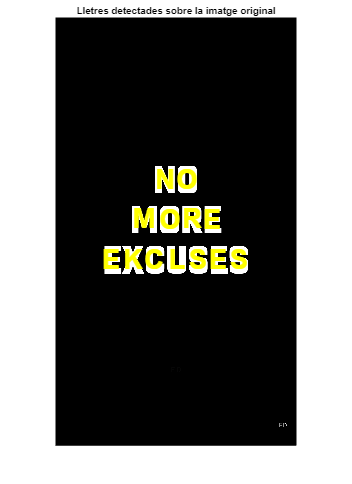


    % Calcular característiques geomètriques bàsiques
    perimeter = sum(bwperim(component, 8), 'all'); % Perímetre
    area = sum(component(:)); % Àrea
    compactness = (perimeter^2) / area; % Compacitat
    aspect_ratio = size(component, 2) / size(component, 1); % Relació d'aspecte

    % Distàncies des del centre de massa
    stats = regionprops(component, 'Centroid');
    [rows, cols] = find(component);

    % Característiques del contorn
    boundary = bwboundaries(component);
    if ~isempty(boundary)
        boundary = boundary{1};
        % Transformada de Fourier del contorn (només els primers 10 coeficients)
        fft_boundary = abs(fft(boundary(:, 1) + 1i * boundary(:, 2)));
        fourier_descriptors = fft_boundary(1:min(10, end));
    else
        fourier_descriptors = zeros(1, 10);

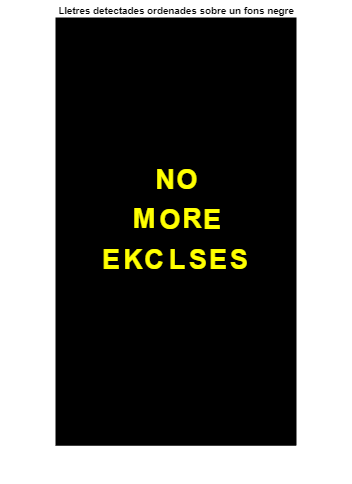

    end

    % Compactar tots els descriptors en un vector
    descriptors = [hog_features, perimeter, area, compactness, aspect_ratio, ...
                   fourier_descriptors(:)'];

    % Normalitzar els descriptors
    descriptors = descriptors / norm(descriptors, 2); % Normalitzar vector
end

% Funció per processar una component segmentada
function skeleton = process_segmented_component(component)

    % Dimensions desitjades per al resize
    resize_dim = [100, 100];
    % Redimensionar
    resized_component = imresize(component, resize_dim);

    cleaned_component = imdilate(resized_component, strel('disk', 1));
    % Convertir a tipus lògic abans de l'esqueletització
    cleaned_component = logical(cleaned_component);
    % Esqueletització
    skeleton = bwskel(cleaned_component);

    thicker_skeleton = imdilate(skeleton, strel('disk', 1));

    % Suavitzar l'esquelet
    skeleton = bwmorph(thicker_skeleton, 'spur', 5);

end

% Funció per garantir dimensions consistents dels descriptors

Text reconegut per OCR:


function descriptor = pad_or_truncate(descriptor, target_length)

NO
MORE
EXCUSES




    if length(descriptor) < target_length
        % Omplir amb zeros fins a la mida desitjada
        descriptor = [descriptor, zeros(1, target_length - length(descriptor))];
    elseif length(descriptor) > target_length
        % Truncar per ajustar a la mida desitjada
        descriptor = descriptor(1:target_length);
    end
end

## 4. Resultats

A continuació es mostren els resultats de l'algorisme

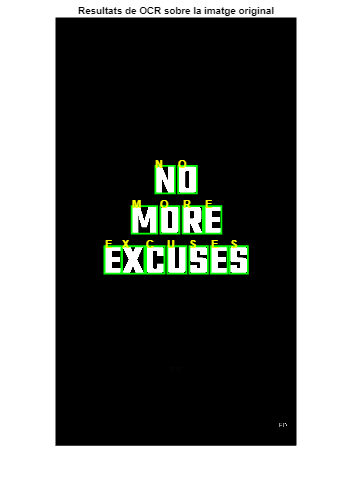

% Mostrar les lletres detectades
for k = 1:num
    fprintf('Component %d: Lletra detectada -> %s\n', k, detected_letters{k});
end

% Mostrar la imatge original
figure;
imshow(img);
title('Lletres detectades sobre la imatge original');

% Afegir text groc per cada component detectada
hold on; % Mantenir la imatge per afegir text

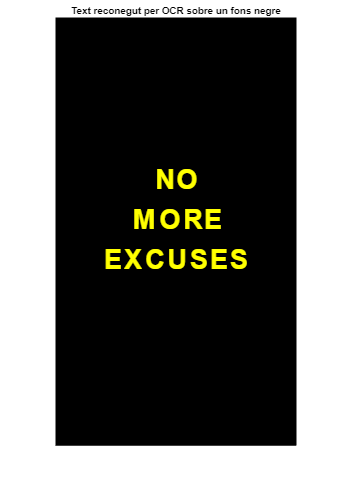


for k = 1:num
    % Coordenades del centroid de cada component
    centroid = stats(k).Centroid;
    
    % Afegir la lletra detectada com a text
    text(centroid(1), centroid(2), detected_letters{k}, ...
        'Color', 'yellow', 'FontSize', 30, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
end

hold off; % Alliberar la imatge
% Dimensions de la imatge original
[img_height, img_width, ~] = size(img);

% Crear una nova imatge de fons negre
black_background = zeros(img_height, img_width, 3, 'uint8');


% Mostrar la imatge de fons negre
figure;
imshow(black_background);
title('Lletres detectades ordenades sobre un fons negre');

% Afegir text groc per cada component detectada
hold on; % Mantenir la imatge per afegir text

for k = 1:num
    % Coordenades del centroid de cada component
    centroid = stats(k).Centroid;
    
    % Afegir la lletra detectada com a text
    text(centroid(1), centroid(2), detected_letters{k}, ...
        'Color', 'yellow', 'FontSize', 30, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
end

hold off;

## 5. Reconeixement de caràcters amb OCR

% Aplicar OCR directament a la imatge binaritzada i netejada
ocr_results = ocr(binary_img_cleaned);

% Mostrar el text reconegut
disp('Text reconegut per OCR:');
disp(ocr_results.Text);

% Mostrar la imatge original amb el text detectat
figure;
imshow(img);
title('Resultats de OCR sobre la imatge original');
hold on;

% Afegir les regions detectades per OCR amb els seus textos
for i = 1:length(ocr_results.CharacterBoundingBoxes)
    bbox = ocr_results.CharacterBoundingBoxes(i, :);
    text_position = [bbox(1), bbox(2) - 10]; % Ajustar per no tapar la regió
    text_detected = ocr_results.Text(i);
    
    % Dibuixar la regió i afegir el text
    rectangle('Position', bbox, 'EdgeColor', 'green', 'LineWidth', 2);
    text(text_position(1), text_position(2), text_detected, ...
        'Color', 'yellow', 'FontSize', 12, 'FontWeight', 'bold');
end

hold off;

% Mostrar el text sobre un fons negre
figure;
imshow(black_background);
title('Text reconegut per OCR sobre un fons negre');
hold on;

% Afegir el text reconegut al fons negre
for i = 1:length(ocr_results.CharacterBoundingBoxes)
    bbox = ocr_results.CharacterBoundingBoxes(i, :);
    centroid = [bbox(1) + bbox(3) / 2, bbox(2) + bbox(4) / 2]; % Centroid aproximat

    text(centroid(1), centroid(2), ocr_results.Text(i), ...
        'Color', 'yellow', 'FontSize', 30, 'FontWeight', 'bold', ...
        'HorizontalAlignment', 'center');
end

hold off;